# 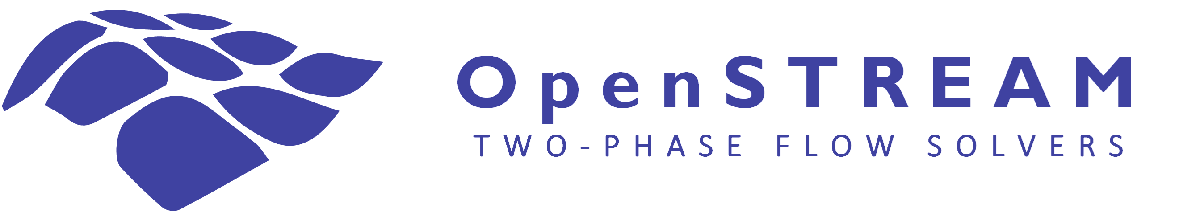

# Tutorial #9: Advanced visualization and post-processing

This tutorial presents the principal OpenSTREAM visualization and post-processing capabilities within a single workflow. A transient mixture-solver calculation is used to demonstrate axial animations, time histories at selected elevations, time-elevation surfaces, direct extraction of calculated quantities, tabular output, and the saving and reloading of solver objects.

The selected geometry consists of a 3.5 m uniformly heated vertical tube with an inner diameter of 8.8 mm, followed by a 2 m adiabatic section with the same diameter.

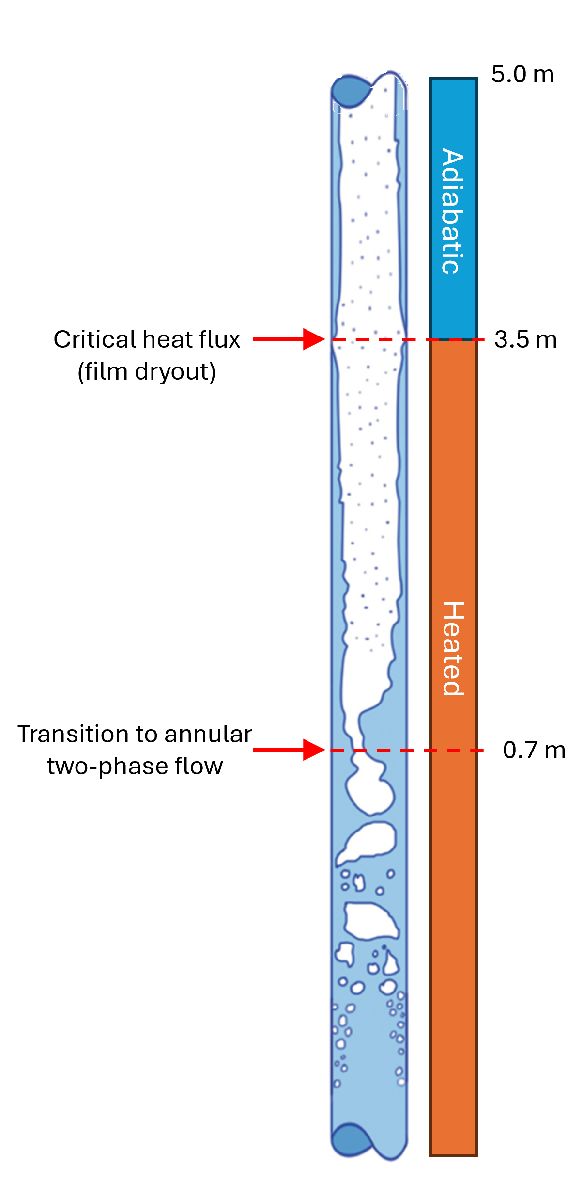

Although the mixture solver is used for demonstration, the same general visualization and post-processing workflow is available across the mixture, two-fluid, three-field, and four-field solvers. The quantities available for plotting and extraction depend on the phases and fields calculated by the selected solver.

After completing this tutorial, you will be able to:

- generate animated axial distributions using plotz;

- generate physical-time histories at selected axial locations using plott;

- visualize the combined spatial and temporal development of a solution using plotzt;

- select specific time indices and axial-node ranges;

- identify the default and solver-specific plotting quantities;

- extract stored solution quantities directly from solver objects;

- assemble selected results into compact MATLAB tables;

- save and reload solver objects for further post-processing without repeating the calculation.

*Note: This tutorial is designed for use with output displayed inline (View > Output Inline) in the MATLAB Live Editor. Any animations are displayed in separate pop-up figure windows and can be played continuously or inspected one stored time step at a time. Animations and their controls are not preserved in static Markdown, HTML, or PDF exports.*

**Important**

*The physical models and closure relations selected in this tutorial are used for educational and demonstration purposes. Their use does not imply that they are appropriate, recommended, or validated for the simulated conditions. The calculated results should therefore be interpreted as illustrations of the solver framework and its capabilities, rather than as validated predictions. Before applying OpenSTREAM to a technical study, assess the assumptions, applicability range, and validation basis of every selected model.*

## Set up OpenSTREAM

Clear existing variables from the workspace.

clearvars

When this tutorial is run directly from the tutorials folder, the OpenSTREAM root directory is one level above the current folder.

osp = './..';
addpath(osp);

Import the input, solver, and mixture-solver packages required by this tutorial.

import Inputs.*
import Solvers.*
import Solvers.Mixture.*

## Create a transient demonstration case

This tutorial uses the mixture solver and the simple transient boundary conditions introduced in Tutorial 2. The prescribed transient consists of a power decrease during the first second, followed by four seconds of operation at the reduced power. All other boundary conditions remain constant.

% Construct the input set.
warning off
inputSet = InputSet( ...
    modelFilePath          = [osp '/inputs/models.inp'], ...
    modelID                = 'TUTORIAL1', ...
    optionsFilePath        = [osp '/inputs/options.inp'], ...
    optionsID              = 'DEFAULT', ...
    geometryFilePath       = [osp '/inputs/geom.inp'], ...
    geometryID             = 'TUTORIAL1', ...
    bcFilePath             = [osp '/inputs/tutorial2_transient.inp'], ...
    sessionParentDir       = fullfile(pwd,'outputs'), ...
    overwriteSessionFiles = true, ...
    LOGMODE                = 'BOTH');
warning on

% Construct and solve the mixture solver.
solver = MixtureSolver(inputSet);
solver.solve();

The solver first reports convergence of the initial steady-state calculation and then advances through the prescribed physical transient. The stored solution can subsequently be examined as axial distributions at selected times, time histories at selected axial locations, or combined time-elevation representations.

The resulting solver object contains:

- the imported model, numerical-option, geometry, and boundary-condition inputs;

- the pseudo-time history used to obtain the initial steady-state solution;

- the calculated physical-time solution;

- the mixture and phase quantities at every stored axial node and physical time;

- pressure-drop and other derived quantities;

- methods for axial, temporal, and time-elevation visualization.

The following sections use this solver object to demonstrate built-in plotting, animation, variable extraction, custom post-processing, and saving and reloading results.

## Animated axial distributions

Use plotz to display axial distributions at selected physical times. Passing an empty first positional argument selects all stored physical time steps. For a transient calculation, this produces an animated axial view; for a steady-state calculation, the result is displayed as a single static frame.

The display option selects the quantities to be plotted. If display is omitted, plotz uses the default set of quantities defined for the selected solver. Because each solver calculates different physical variables, the default displayed quantities may differ among the mixture, two-fluid, three-field, and four-field solvers.

solver.plotz([], ...
    'display', {'HFLUX','W','VR'}, ...
    'arrangement', 'horizontal', ...
    'resize', 1);

Each animation frame shows the axial distributions at one stored physical time step. The displayed quantities include the wall heat flux, mass flow rates, equilibrium and vapor mass qualities, and void fraction.

The animation begins with the converged steady-state solution used to initialize the physical transient. Subsequent frames show how the solution evolves during the prescribed power decrease and the following period at reduced power.

Use the figure controls to play the animation continuously or move manually from one stored time step to another. By default, the animation frame rate is adjusted automatically to reproduce the transient at approximately real-time speed. The playback rate can be changed manually using the fps field in the animation window. The arrow buttons allow individual stored time steps to be inspected, while the play button displays the complete sequence continuously or in a loop. This view is useful for examining where the transient response first becomes visible, how changes propagate along the channel, and which regions respond most strongly.

In this example, the wall heat flux decreases during the first second and subsequently remains at its reduced value. The mass flow rates, vapor mass quality, and void fraction adjust progressively as the flow responds to the new heating conditions. Comparing individual frames reveals both the spatial distribution of the response and the time required for different channel regions to adjust.

Instead of displaying every stored physical time step, the first positional argument of plotz can be used to select specific time indices. The zIdx option can similarly be used to restrict the displayed axial range. This is useful when only selected states or channel regions are needed for comparison, interpretation, or publication.

% Select the initial, intermediate, and final stored physical states.
tIdx = unique([ ...
    1, ...
    round(solver.NTIME/2), ...
    solver.NTIME]);

% Select the heated section, including its upper boundary.
zIdx = find(solver.Z <= 3.5);

solver.plotz( ...
    tIdx, ...
    'zIdx', zIdx, ...
    'display', {'HFLUX','W','VR'}, ...
    'arrangement', 'horizontal', ...
    'resize', 1);

The resulting animation contains only the initial, intermediate, and final selected states and displays only the heated section of the channel. The animation controls can be used to move between these states and compare the evolution of the wall heat flux, mass flow rates, vapor mass quality, and void fraction within the selected region.

## Time histories at selected elevations

Use plott to display the evolution of calculated quantities at a selected axial node. The first positional argument specifies the axial-node index. If the tIdx option is omitted, all stored physical time steps are displayed.

The following examples show the wall heat flux, mixture, liquid, and vapor mass flow rates, together with the equilibrium quality, vapor mass quality, and void fraction at three axial locations.

% Near the channel inlet
% Select the third axial node to avoid displaying only the imposed inlet boundary values.
solver.plott(3, ...
    'display', {'HFLUX','W','VR'}, ...
    'arrangement', 'horizontal', ...
    'resize', 1);

% Near the channel midpoint
solver.plott(round(solver.NZ/2), ...
    'display', {'HFLUX','W','VR'}, ...
    'arrangement', 'horizontal', ...
    'resize', 1);

% At the channel outlet
solver.plott(solver.NZ, ...
    'display', {'HFLUX','W','VR'}, ...
    'arrangement', 'horizontal', ...
    'resize', 1);

Each figure shows how the selected quantities evolve with physical time at one fixed axial location. Comparing the three locations helps reveal how the transient response varies along the channel.

Near the inlet, the flow remains closer to the imposed inlet condition and generally responds less strongly to the power reduction. Farther downstream, the accumulated effect of wall heating produces a larger vapor content, and changes in vapor mass quality and void fraction become more pronounced. The outlet history reflects the integrated response of the complete channel.

The wall heat-flux histories directly reproduce the prescribed power decrease during the first second and the subsequent period at reduced power. Because the channel outlet is located in the adiabatic section, its wall heat flux remains zero throughout the transient. Nevertheless, the outlet mass-flow-rate and vapor-ratio histories continue to evolve as the effects of the upstream heating change propagate through the channel. Comparing the three axial locations therefore illustrates both the spatial distribution of the transient response and the different adjustment rates of the channel regions.

## Time-elevation surfaces

Use plotzt to visualize how a calculated quantity varies simultaneously with physical time and axial elevation. This representation complements:

- plotz, which displays axial distributions at selected times;

- plott, which displays time histories at selected axial locations.

Unlike plotz and plott, the display option of plotzt uses the exact property names stored in the solver fields. Each requested property is displayed as an individual time-elevation surface.

% Plot the wall heat flux and total mass flow rate.
solver.plotzt( ...
    'display', {'HFLUX','W'});

% Plot the vapor mass quality and void fraction.
solver.plotzt( ...
    'display', {'X','VF'});

Each surface represents one calculated variable as a function of physical time and axial elevation. This view is particularly useful for identifying:

- where a transient response first appears;

- how the response develops and propagates along the channel;

- whether different channel regions respond at different rates;

- how axial gradients change during the transient;

- whether local extrema or transition locations move with time.

The wall heat-flux surface shows the prescribed power decrease in the heated section during the first second. The heat flux remains zero in the downstream adiabatic section. The mass-flow-rate, vapor-mass-quality, and void-fraction surfaces show how the fluid response develops throughout the channel as the heating conditions change.

Because plotzt requires exact solver-property names, the available display values depend on the selected solver and field object. For example, W, X, and VF are properties available in the mixture solution, while the two-fluid, three-field, and four-field solvers expose additional phase- and field-specific properties. Consult the corresponding solver and field objects when selecting quantities for a time-elevation plot.

## Direct data extraction

The calculated results can be accessed directly from the stored solver objects. This is useful for creating tables, performing custom calculations, exporting selected results, or developing user-defined plots.

The transient method extracts the time history of a specified property at a selected axial node. The following example creates a compact table containing the physical time, total pressure drop, and vapor mass quality at the channel outlet.

% Extract the stored physical times.
time = [solver.mixture.TIME].';

% Extract the total pressure drop at the channel outlet.
outletPressureDrop = solver.mixture.transient( ...
    'DP.Tot', ...
    'zIdx', solver.NZ).';

% Extract the vapor mass quality at the channel outlet.
outletQuality = solver.mixture.transient( ...
    'X', ...
    'zIdx', solver.NZ).';

% Assemble the extracted results in a table.
parameterTable = table( ...
    time, ...
    outletPressureDrop, ...
    outletQuality, ...
    'VariableNames', { ...
        'Time_s', ...
        'OutletPressureDrop_Pa', ...
        'OutletVaporMassQuality'});

disp(parameterTable)

Each row of the table corresponds to one stored physical time. The table provides a compact representation of the outlet response and can be used for further analysis or exported to another file format.

The property name supplied to transient must correspond to a property available in the selected solver field. A nested property can be accessed using dot notation. In this example, DP.Tot extracts the total pressure-drop contribution stored within the DP object, while X extracts the vapor mass quality.

The axial location is selected using zIdx. Here, solver.NZ identifies the final axial node and therefore extracts the channel-outlet values. Other axial locations can be selected by supplying a different node index.

The table can be exported to CSV for use in another analysis environment or for inclusion in a reproducible post-processing workflow.

outputFile = fullfile( ...
    pwd, ...
    'outputs', ...
    'tutorial9_outlet_results.csv');

writetable( ...
    parameterTable, ...
    outputFile);

fprintf( ...
    'Outlet results exported to:\n%s\n', ...
    outputFile);

## Save and reload a solver object

Save the solver object in MATLAB binary format so that the inputs, stored solution fields, and session information can be reused without rerunning the calculation.

By default, OpenSTREAM stores the file in the solver’s session directory. The directory name combines the geometry, model, and numerical-option IDs:

`<geometry ID>-<model ID>-<option ID>`

For this case, the directory is:

`TUTORIAL1-TUTORIAL1-DEFAULT`

The generated MAT-file name identifies the boundary-condition file and solver type:

`tutorial2_transient_MixtureSolver.mat`

The name option specifies the variable name used to store the solver object in the MAT-file. Here, the object is saved as solver, but any valid MATLAB variable name can be selected. After loading the file, use that variable name for subsequent plotting and post-processing.

% Save the solver object.
solver.save( ...
    'name', 'solver', ...
    'showpath', false);

Clear the current workspace to demonstrate that the saved result can be restored independently.

clearvars

Load the MAT-file into a structure and restore the saved solver object.

% Define the saved solver-file path.
solverFile = fullfile( ...
    'outputs', ...
    'TUTORIAL1-TUTORIAL1-DEFAULT', ...
    'tutorial2_transient_MixtureSolver.mat');

% Load the saved data without placing variables directly in the workspace.
savedData = load(solverFile);

% Restore the solver object.
solver = savedData.solver;

Inspect the restored object.

disp(solver)

Reproduce an axial animation directly from the stored solution.

solver.plotz( ...
    [], ...
    'display', {'HFLUX','W','VR'}, ...
    'arrangement', 'horizontal', ...
    'resize', 1);

The restored solver contains the previously calculated physical-time solution, so the plotting and post-processing methods can be used without repeating the steady-state initialization or physical transient calculation. Other variable names can be supplied through the name option when saving, but the same name must then be used when retrieving the object from the loaded MAT-file.

## Summary

In this tutorial, you explored OpenSTREAM’s built-in visualization and post-processing capabilities, including animated axial distributions, time histories at selected elevations, time-elevation surfaces, direct data extraction, and custom result tables. You also saved and reloaded a solver object for further analysis without repeating the calculation. Similar plotting and post-processing capabilities are available across all OpenSTREAM solvers, with solver-specific variables and display options.